# BME3053C Final Project

Authors: Gabriel Iglesias Maldonado, Andrea Lopez, Ben Kaufman

Course: BME 3053C Computer Applications for BME

Term: Spring 2021

J. Crayton Pruitt Family Department of Biomedical Engineering

University of Florida

April 16, 2021

clc;clear;

retreive images

list = dir("Cataracts/");
list(1:2,:) = [];

read image

input = input("Enter image number between 1 and 29: ");
for ii = input
i=imread(list(ii).name);

image plotting

figure(1)
sgtitle("Cataracts Image Processing")

grayscale image processing

i_gray = rgb2gray(i);

image plotting

subplot(2,2,1);
imshow(i_gray);
title("Greyscale")

green component image processing

green_component = i(:,:,2);
inverse=imcomplement(green_component);

image plotting

subplot(2,2,2);
imshow(inverse);
title("Inverted")

image contrast enhancement (CLAHE)

iadapt=adapthisteq(inverse,'cliplimit',.01);

2-D gaussian filtering

blur=imgaussfilt(iadapt);

tophat transform

se=strel('disk',12);
black=imtophat(iadapt,se);

adjust image intensity

contrast=imadjust(black);

graythreshold

gray=graythresh(contrast);

binarization

binarize = imbinarize(contrast,gray);
bw=bwareaopen(binarize,30);
fill=imfill(bw,'holes');

image plotting

subplot(2,2,3);
imshow(bw);
title("Black and White")

image plotting

subplot(2,2,4);
imshow(inverse);
title("Highlighted Eye");

Determination of the circle containing the iris

[centers,radii,metric] = imfindcircles(fill, [25 10000]);
if length(centers) ~= 2
    fprintf("Error: Iris not detected \n");
else
    centersStrong5 = centers(1:1,:); 
    radiiStrong5 = radii(1:1);
    metricStrong5 = metric(1:1);
    viscircles(centersStrong5, radiiStrong5,'EdgeColor','b');

Calculating the ratio of black pixels to white pixels inside of the determined circle

bk=0;
wh=0;
[l,w] = size(bw);
for ii = 1:1:l
    for jj = 1:1:w
        if (ii-centers(1))^2 + (jj-centers(2)) ^2  <= radii^2
            if bw(ii,jj) == 0
                bk = bk + 1;
            else
                wh = wh + 1;
            end
        end
    end
end

ratio = bk/(bk+wh)

Make diagnosis using calculated ratio

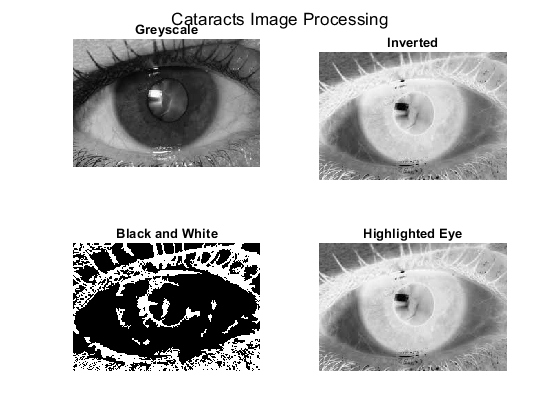

Error: Iris not detected 


if ratio > .61
    disp('Likely has cataract')
else
    disp('Cataract is unlikely')
end

end

end